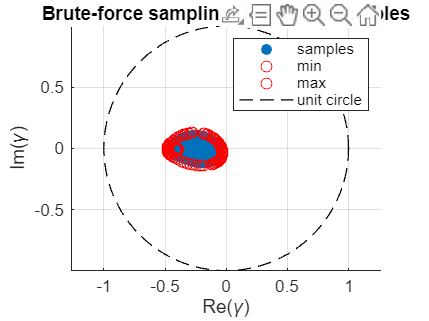

clear;
%run("data/c3x7_s1602_l48.m");
%run("data/c3x7_s1794_l290.m");
%run("data/c3x7_s1914_l275.m")
run("data\c7x17_s1794_l290.m")
T = (T11 + T22) /2;
%A = (O12 + O12')/2;

%[V, D, W] = eig(A, T)

% [Re_gamma_max, id_max] = max(diag(D))
% [Re_gamma_min, id_min] = min(diag(D))
% 
% w_max = W(:, id_max)
% w_min = W(:, id_min)
% 
% num_min = w_min' * O12 * w_min;
% denom_min = sqrt((w_min' * T11 * w_min) * (w_min' * T22 * w_min));
% 
% num_max = w_max' * O12 * w_max;
% denom_max = sqrt((w_max' * T11 * w_max) * (w_max' * T22 * w_max));
% 
% gamma_min = num_min/denom_min
% gamma_max = num_max/denom_max
% M = 60; % number of random polarization samples (adjust)
% boundary_vals = complex(zeros(M,2));

% for k = 0:59
% A = (O12*exp(i*(pi-pi*k/59)) + O12'*exp(i*(pi-pi*k/59)))/2;
% [V, D, W] = eig(A, T);
% [Re_gamma_max, id_max] = max(diag(D));
% [Re_gamma_min, id_min] = min(diag(D));
% w_max = W(:, id_max);
% w_min = W(:, id_min);
% num_min = w_min' * O12 * w_min;
% denom_min = sqrt((w_min' * T11 * w_min) * (w_min' * T22 * w_min));
% 
% num_max = w_max' * O12 * w_max;
% denom_max = sqrt((w_max' * T11 * w_max) * (w_max' * T22 * w_max));
% 
% gamma_min = num_min/denom_min;
% gamma_max = num_max/denom_max;
% boundary_vals(k+1,1)=gamma_min;
% boundary_vals(k+1,2)=gamma_max;
% end

phi = linspace(0, pi, 60);  % 0 to pi

boundary_vals = zeros(length(phi), 2);  % preallocate

for k = 1:length(phi)
    % Hermitian part of phase-rotated O12
    A = (O12*exp(1j*phi(k)) + (O12*exp(1j*phi(k)))')/2;

    % Generalized eigenproblem
    [V,D] = eig(A, T);

    % Max and min Re(γ)
    [~, id_max] = max(diag(D));
    [~, id_min] = min(diag(D));

    w_max = V(:, id_max);
    w_min = V(:, id_min);

    % Normalized gamma
    gamma_max = (w_max' * O12 * w_max) / sqrt( (w_max' * T11 * w_max) * (w_max' * T22 * w_max) );
    gamma_min = (w_min' * O12 * w_min) / sqrt( (w_min' * T11 * w_min) * (w_min' * T22 * w_min) );

    boundary_vals(k,1) = gamma_min;
    boundary_vals(k,2) = gamma_max;
end



% Precompute for speed if needed
% We'll compute gamma(w) directly for many w vectors:
N = 20000; % number of random polarization samples (adjust)
gamma_vals = complex(zeros(N,1));
%3xN matrix
w_store = complex(zeros(3,N));

% sample w uniformly on complex unit sphere
%We dont need to check for repeated samples, because we are sampling from a
%continious distribution. So statistaclly we should not get identical
%samples.
for k = 1:N
    % randn(3,1) creates three random normally distrubited numbers, so that
    % we are uniform on the complex sphere.
    z = (randn(3,1) + 1i*randn(3,1));
    %Normalize
    w = z / norm(z);
    %Store the value
    w_store(:,k) = w;
    %Calculate numerator
    num = w' * O12 * w;
    %Calculate denomerator
    denom = sqrt((w' * T11 * w) * (w' * T22 * w));
    %calculate gamma and store it
    gamma_vals(k) = num / denom;
end

% --- Plot the brute-force sampled points ---
figure('Name','Brute-force coherence sampling','NumberTitle','off');
hold on;  % keep all plots in the same figure
axis equal; grid on;

% scatter plot of your samples
scatter(real(gamma_vals), imag(gamma_vals), 8, 'filled');

scatter(real(boundary_vals(:,1)), imag(boundary_vals(:,1)), 'ro', 'red');
scatter(real(boundary_vals(:,2)), imag(boundary_vals(:,2)), 'ro', 'red');

% plot special point numerator
% plot(real(gamma_min), imag(gamma_min), '*', 'MarkerSize',8, 'LineWidth',2);
% 
% plot(real(gamma_max), imag(gamma_max), 'ro', 'MarkerSize',8, 'LineWidth',2);

% draw unit circle for reference
th = linspace(0,2*pi,500);
plot(cos(th), sin(th), 'k--', 'LineWidth', 0.7);

% labels and title
xlabel('Re(\gamma)'); 
ylabel('Im(\gamma)');
title(sprintf('Brute-force sampling: N = %d samples', N));

% legend
legend('samples','min','max', 'unit circle');

hold off;  % optional, release hold